clf;
clear;

house = imread("../images/man_in_house.png");
[M,N] = size(house)

M = 600

N = 800

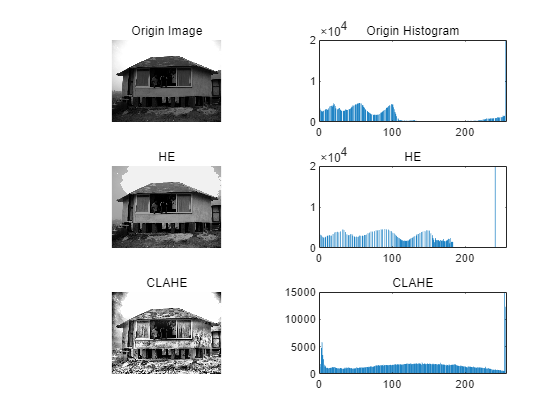

%house = house(:,:,1);
%imshow(house);

I_hist = my_hist(house);

% HE function
T = zeros(1,256);
for k = 1:256
    if k == 1
        T(k) = 255*I_hist(k)/M/N;
    else
        T(k) = T(k-1) + 255*I_hist(k)/M/N;
    end
end

% adapt HE
house_HE = zeros(M,N);
for m = 1:M
    for n = 1:N
        for k = 1:256
            if house(m,n) == k
                house_HE(m,n) = round(T(k));
            end
        end
    end
end

house_HE = uint8(house_HE);
% house_HE = histeq(house,256); % for check
house_CLAHE = my_CLAHE(house,50,0.1); % Reference: source code of MATLAB
house_CLAHE = uint8(house_CLAHE);
% house_CLAHE = adapthisteq(house);
subplot(3,2,1);
imshow(house);title('Origin Image');
subplot(3,2,2);
bar(I_hist);title('Origin Histogram'); 
ylim([0,2e4]);
subplot(3,2,3);
imshow(house_HE);title('HE');
subplot(3,2,4);
bar(my_hist(house_HE));title('HE');
ylim([0,2e4]);
subplot(3,2,5)
imshow(house_CLAHE);title('CLAHE');
subplot(3,2,6);
bar(my_hist(house_CLAHE));title('CLAHE');
ylim([0,1.5e4]);

% Reference: source code of MATLAB

function clahe_I = my_CLAHE(I,divide,cliplimit)
% Setup
size_I = size(I);
size_tile = [size_I(1)/divide size_I(2)/divide];
dim_tile = size_I ./ size_tile;
pixel = prod(dim_tile);
min_cliplimit = ceil(pixel/256);
ClipLimit = min_cliplimit + round(cliplimit*(pixel-min_cliplimit));

tile_mapping = cell(size_tile);
col = 1;
for i=1:size_tile(2)
    row = 1;
    for j=1:size_tile(1)
        tile = I(row:row+dim_tile(1)-1,col:col+dim_tile(2)-1);
        tile_hist = my_hist(tile);

        excess = sum(max(tile_hist-ClipLimit,0)); % num of excess limit
        avg = floor(excess/256);
        upper = ClipLimit - avg;

        % Collect Excess and Redistribute this hist
        for k=1:256
            if tile_hist(k) > ClipLimit
                tile_hist(k) = ClipLimit;
            else
                if tile_hist(k) > upper
                    excess = excess - (ClipLimit - tile_hist(k));
                    tile_hist(k) = ClipLimit;
                else
                    excess = excess - avg;
                    tile_hist(k) = tile_hist(k) + avg;
                end
            end
        end
        
        % Redistribute the remaining pixels
        k = 1;
        while (excess ~= 0)
            for m=k:max(floor(256/excess),1):256
                if tile_hist(m) < ClipLimit
                    tile_hist(m) = tile_hist(m)+1;
                    excess = excess - 1;
                    if excess == 0
                        break;
                    end
                end
            end
        end
        
        % HE mapping
        hist_sum = cumsum(tile_hist);
        scale  = 255/pixel;
        % uniform
        mapping = min(hist_sum*scale, 255);

        tile_mapping{j,i} = mapping;
        row = row + dim_tile(1);
    end
    col = col + dim_tile(2);
end

% Insert
clahe_I = zeros(size_I(1),size_I(2));
tile_row=1;
for r=1:size_tile(1)+1
    if r == 1 % top
        num_row = dim_tile(1)/2; % divisible by 2 because of padding
        map_row = [1 1];
    else 
        if r == size_tile(1)+1 % bottom     
            num_row = dim_tile(1)/2;
            map_row = [size_tile(1) size_tile(1)];
        else
            num_row = dim_tile(1);
            map_row = [r-1, r];
        end
    end
  
    tile_col=1;
    for c=1:size_tile(2)+1
        if c == 1 % left
            num_col = dim_tile(1)/2;
            map_col = [1, 1];
        else
            if c == size_tile(2)+1 % right
                num_col = dim_tile(1)/2;
                map_col = [size_tile(2), size_tile(2)];
            else
                num_col = dim_tile(2);
                map_col = [c-1, c];
            end
        end
        
        % Extract tile mappings
        up_left = tile_mapping{map_row(1), map_col(1)};
        up_right = tile_mapping{map_row(1), map_col(2)};
        bottom_left = tile_mapping{map_row(2), map_col(1)};
        bottom_right = tile_mapping{map_row(2), map_col(2)};
    
        for i = 1:num_row
            for j = 1:num_col
                row = tile_row+i-1;
                col  = tile_col+j-1;
                
                clahe_I(row, col) = ...
                    ((num_row-i)*((num_col-j)*double(up_left(I(row,col)+1))+j*double(up_right(I(row,col)+1)))+...
                    i*((num_col-j)*double(bottom_left(I(row,col)+1))+j*double(bottom_right(I(row,col)+1))))/(num_row*num_col);
            end
        end
        tile_col = tile_col + num_col;    
    end
    tile_row = tile_row + num_row;
end
end

%==============================================================
% Get histogram
function output = my_hist(input)
[M,N] = size(input);
output = zeros(1,256);

for k = 1:256
    for m = 1:M
        for n = 1:N
            output(k) = output(k) + (input(m,n) == k);
        end
    end
end
end